# Laboratorium 8

Janusz Pawlicki

## Zad1

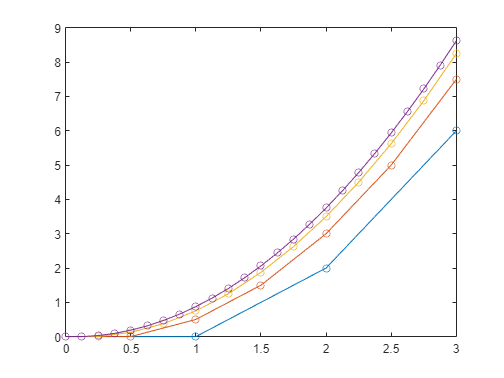

clear;

N = 3;
h = [1, 0.5, 0.25, 0.125];
y(1)=0;

for j=1:length(h)
    t=0:h(j):N; 
    for i=1:N/h(j)
        dy=2*t(i);
        y(i+1)=y(i)+dy*h(j);
    end
    
    plot(t,y,'-o')
    hold on;
end
hold off

## Zad2

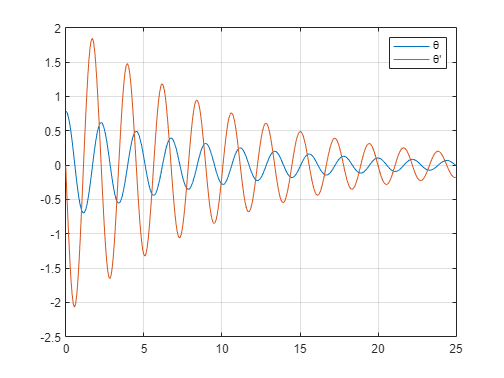

clear;

opts=odeset('stats','on');

tspan=[0 25];
y0 = [pi/4, 0];

[t,y] = ode45(@wahadlo, tspan, y0, opts);

plot(t,y(:,1),t,y(:,2))
grid on;
legend('\theta','\theta''')

## Zad3

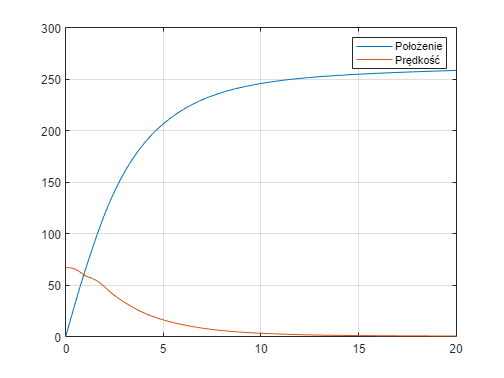

global w3;
opts = odeset('stats','on');
 
t,y] = ode45(@hamownik, [0 20], [0 67 0 0 0 0], opts);
figure
plot(t,y(:,1),t,y(:,2))
grid on
legend('Położenie', 'Prędkość')

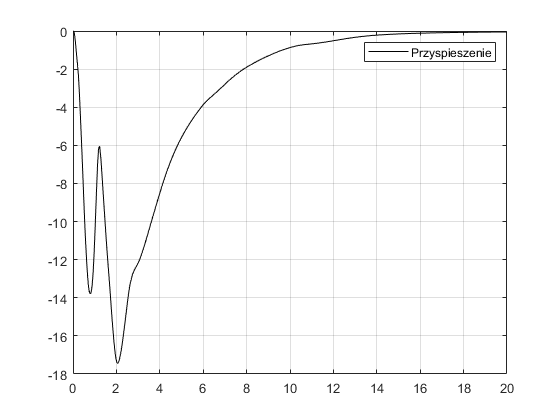

 
options = odeset('OutputFcn',@hamownik_out,'Refine',1);
 
[T,Y] = ode45(@hamownik, [0 20], [0 67 0 0 0 0], options);
figure
plot(T,w3,'k')
grid on;
legend('Przyspieszenie');